% Variables used in all my functions
data = info.analysis{1, 1}.respMatPlot;
errorBars = info.analysis{1, 1}.respMatSemPlot;
TimeXs = info.analysis{1, 1}.timeX / 1000;  % ms to s
nEpochs = length(data(1,:));
colors = linspecer(nEpochs,'sequential');
epochNames = cellstr(exp.param_file(3, 3:end)); % do I want to do this like how I did epochDur instead?
epochProbeDur = [exp.params(:).duration];
epochDur = epochProbeDur(param.interleave_epochs+1:end);

pos0 = [exp.params(:).relativeX];
pos0 = pos0(param.interleave_epochs+1:end);
stimPos = cell(1, length(pos0));
stimEndPos = ones(length(pos0),1);

meanData = ones(length(pos0),1);
sdData = ones(length(pos0),1);
semData = ones(length(pos0),1);

for jj = 1:length(pos0)
    stimPos{1,jj} = pos0(jj) + TimeXs;
    stimEndPos(jj) = pos0(jj) + (epochDur(jj)/60);

    % t = 0 to 1.0 s
    meanData(jj) = mean(data(26:40,jj));
    sdData(jj) = std(data(26:40,jj));
    semData(jj) = std(data(26:40,jj)) ./ sqrt(40-26);

    % t = 0 to end
    meanData2(jj) = mean(data(26:end,jj));
    sdData2(jj) = std(data(26:end,jj));
    semData2(jj) = std(data(26:end,jj)) ./ sqrt(74-26);
end

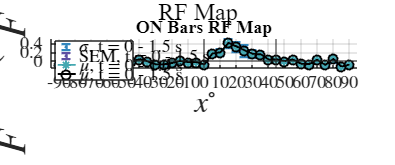

Fig_03c = figure('Units', 'normalized', 'OuterPosition', [0, 0, 1, 1]);
% Subplot 1: ON bars
subplot(3,6,1:6)
hold on;

% Plot mean with error bars (SD and SEM)
% % % errorbar(pos0(1:37), meanData(1:37), sdData(1:37), '.', 'color', colors(4,:), 'LineWidth', 1.5);
% % % errorbar(pos0(1:37), meanData(1:37), semData(1:37), '.','color', colors(1,:), 'LineWidth', 1.5);
% % % plot(pos0(1:37),meanData(1:37), '-o', 'color', 'm', 'LineWidth', 1.25)
errorbar(pos0(1:37), meanData2(1:37), sdData2(1:37), '.', 'color', colors(8,:), 'LineWidth', 1.5);
errorbar(pos0(1:37), meanData2(1:37), semData2(1:37), '.','color', colors(1,:), 'LineWidth', 1.5);
plot(pos0(1:37), meanData(1:37), '-*', 'color', colors(12,:), 'LineWidth', 1.25)
plot(pos0(1:37), meanData2(1:37), '-o', 'color', 'k', 'LineWidth', 1.25)


xline(0,'-')
xline(-45,'-')
xline(45,'-')
yline(0,'-')

set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 12);
grid on;
axis tight;
sgtitle({[num2str(param.cellType),' > ',num2str(param.sensor),' || Flies: ', num2str(info.analysis{1,1}.numFlies)], 'RF Map'}, 'FontSize', 16, 'FontName', 'Times New Roman', 'Interpreter', 'none');
title('ON Bars RF Map', 'FontSize', 12, 'FontName', 'Times New Roman', 'Interpreter', 'none');
xlabel('$x^\circ$', 'FontSize', 20, 'Interpreter', 'latex');
xticks(-90:10:90);  % Set the x-ticks from -90 to 90 in increments of 10
xticklabels(-90:10:90);  % Use the same values for x-tick labels
ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'FontSize', 28, 'Interpreter', 'latex');
xlim([-95,95]);
legend({'$\sigma$, t = 0 - 1.5 s', 'SEM, t = 0 - 1.5 s', '$\mu$, t = 0 - 1.0 s', '$\mu$, t = 0 - 1.5 s'}, 'Interpreter', 'Latex', 'Location', 'NorthWest', 'FontName', 'Times New Roman', 'FontSize', 12);

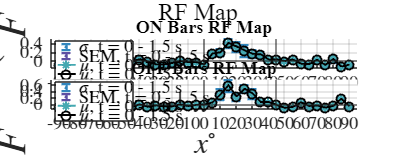

% % % Fig_03d = figure('Units', 'normalized', 'OuterPosition', [0, 0, 1, 1]);
% Subplot 2: OFF bars
subplot(3,6,7:12)
hold on;

% Plot mean with error bars (SD and SEM)
% % % errorbar(pos0(1:37), meanData(1:37), sdData(1:37), '.', 'color', colors(4,:), 'LineWidth', 1.5);
% % % errorbar(pos0(1:37), meanData(1:37), semData(1:37), '.','color', colors(1,:), 'LineWidth', 1.5);
% % % plot(pos0(1:37),meanData(1:37), '-o', 'color', 'm', 'LineWidth', 1.25)
errorbar(pos0(38:end), meanData2(38:end), sdData2(38:end), '.', 'color', colors(8,:), 'LineWidth', 1.5);
errorbar(pos0(38:end), meanData2(38:end), semData2(38:end), '.','color', colors(1,:), 'LineWidth', 1.5);
plot(pos0(38:end), meanData(38:end), '-*', 'color', colors(12,:), 'LineWidth', 1.25)
plot(pos0(38:end), meanData2(38:end), '-o', 'color', 'k', 'LineWidth', 1.25)


xline(0,'-')
xline(-45,'-')
xline(45,'-')
yline(0,'-')

set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 12);
grid on;
axis tight;
title('OFF Bars RF Map', 'FontSize', 12, 'FontName', 'Times New Roman', 'Interpreter', 'none');
xlabel('$x^\circ$', 'FontSize', 20, 'Interpreter', 'latex');
xticks(-90:10:90);  % Set the x-ticks from -90 to 90 in increments of 10
xticklabels(-90:10:90);  % Use the same values for x-tick labels
xlim([-95,95]);
legend({'$\sigma$, t = 0 - 1.5 s', 'SEM, t = 0 - 1.5 s', '$\mu$, t = 0 - 1.0 s', '$\mu$, t = 0 - 1.5 s'}, 'Interpreter', 'Latex', 'Location', 'NorthWest', 'FontName', 'Times New Roman', 'FontSize', 12);

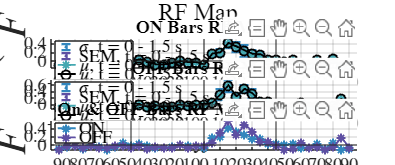

subplot(3,6,13:18)
hold on;

% plot(pos0(1:37), meanData(1:37), ':*', 'color', colors(12,:), 'LineWidth', 1.25)
plot(pos0(1:37), meanData2(1:37), '-*', 'color', colors(8,:), 'LineWidth', 1.25)
% plot(pos0(38:end), meanData(38:end), '-*', 'color', 'k', 'LineWidth', 1.25)
plot(pos0(38:end), meanData2(38:end), '-*', 'color', colors(1,:), 'LineWidth', 1.25)
xline(0,'-')
xline(-45,'-')
xline(45,'-')
yline(0,'-')

set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 12);
grid on;
axis tight;
title('On & OFF Bars RF Map || t = 0 - 1.5 s', 'FontSize', 12, 'FontName', 'Times New Roman', 'Interpreter', 'none');
xlabel('$x^\circ$', 'FontSize', 20, 'Interpreter', 'latex');
xticks(-90:10:90);  % Set the x-ticks from -90 to 90 in increments of 10
xticklabels(-90:10:90);  % Use the same values for x-tick labels
xlim([-95,95]);
legend({'ON','OFF'}, 'Interpreter', 'Latex', 'Location', 'NorthWest', 'FontName', 'Times New Roman', 'FontSize', 12);